nice publication quality figures

nMax1Color= [0 0.5 0]

nMax1Color =          0    0.5000         0


nMaxInfColor= [0 0 0.5]

nMaxInfColor =          0         0    0.5000


**Exemplar trajectories**

rng('default');%initialize RNG for reproducibility

%choose params which support stable tug of war, ie
% high native processivity, low PG unbinding rate eps0<< koff0
% frequent PG binding, pi0>> kOn0
% otherwise based on experimental data rates

motorState.kOn0 = 0.5/60; %rate of single motor (synthase) binding to cargo (mreB) (From Stu data)
motorState.pi0 =10*motorState.kOn0; %single motor binding rate s^-1 %promotes tug of war
motorState.eps0=0.3/60;%single motor unbinding rate s^-1 %promotes tug of war, also at low concentration 
% derived from Stu data)
%processivity is synthesis limited
motorState.kOff0 = 10*motorState.eps0; %rate of single motor (synthase) unbinding from cargo (mreB)
motorState.Fdetach = 1;%detachment force pN nm
motorState.Fstall = 100; %stall force pN nM
motorState.vF=40;%forward velocity nm/s
motorState.vB=0.1;%backward velocity nm/s

motorState.Nplus=0;%initial total number of plus motors 
motorState.Nminus=0;%initial total number of bound plus motors 
motorState.nPlus=0;%number of bound plus motors 
motorState.nMinus=0;%number of bound minus motors

simPar.nStep= 100;
simPar.doFixedTime=true;
simPar.simTime = 2000;

**Nmax=1**

%Nmax = 1 each side (max number of motors), low concentration, which should give frequent pausing model
motorState.Nmax = 1;


**Low concentration**

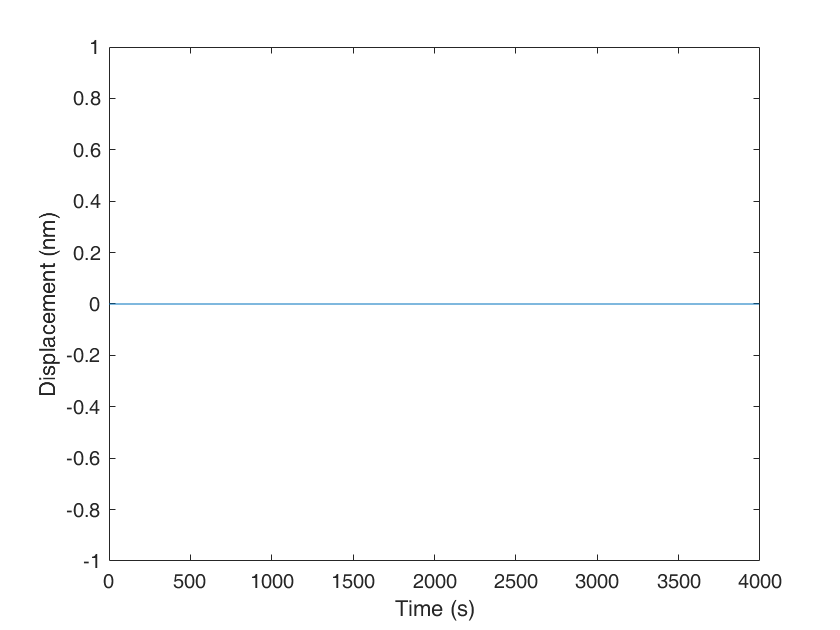

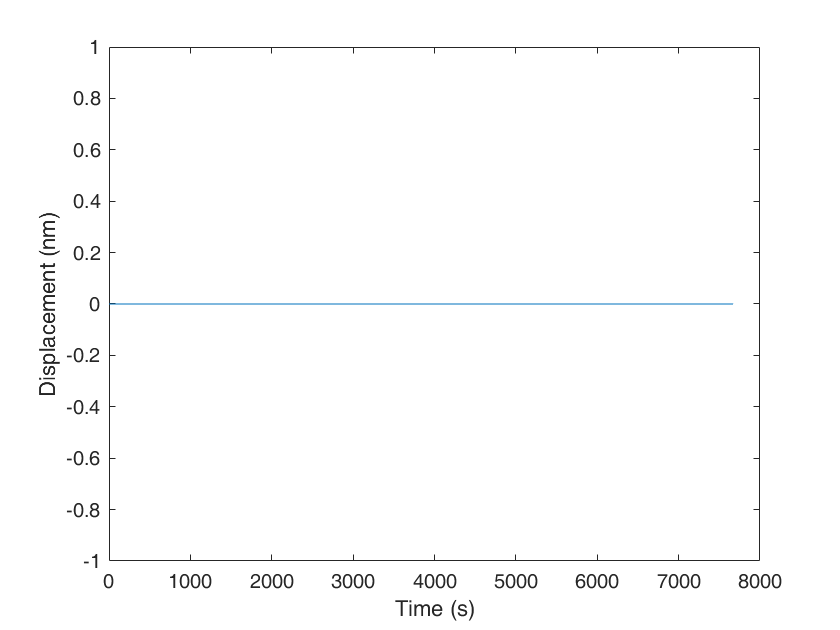

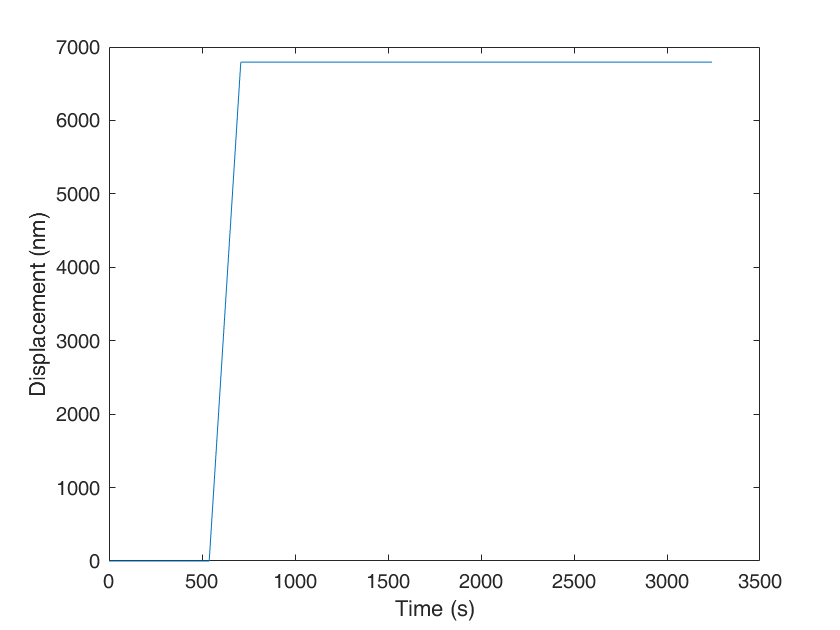

motorState.motorConcentration =1e-2;%arb units, essentiall scaling of low synthase concentration data here

for ii=1:3
    [dynamics] = lipowskiWithUnbindingSim(motorState,simPar);
    t=dynamics.t;
    x=dynamics.x;
    dynamics1Low{ii}=dynamics;
    motorTot= dynamics.Nminus+dynamics.Nplus;
    figure;
%     yyaxis left;
    plot(t,x);
    ylabel('Displacement (nm)');
%     yyaxis right % not showing it this way because the overlay looks
%     fuggly
%     stairs(t,motorTot);
%     ylabel('No. of bound synthases')
    xlabel('Time (s)');
    
end

Best example low conc, 3

**Intermediate concentration**

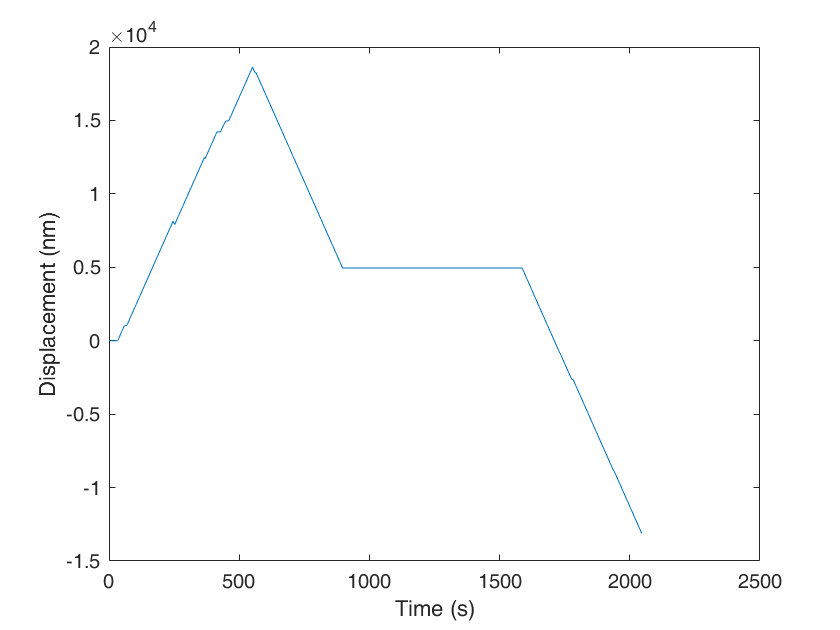

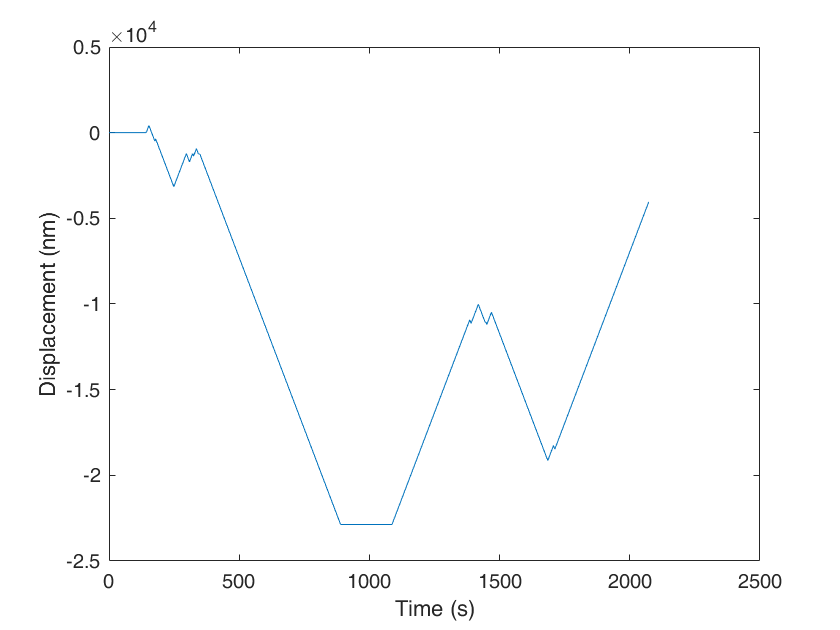

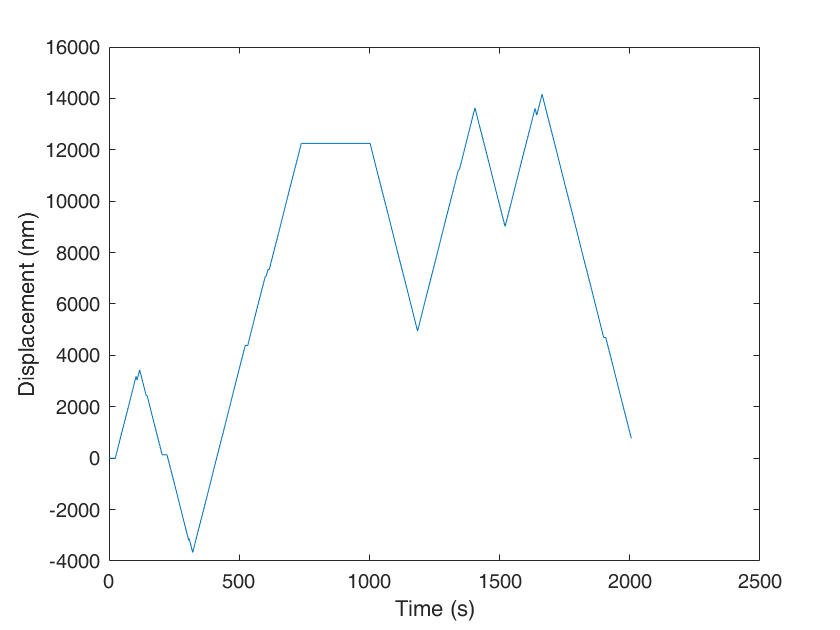

motorState.motorConcentration =1e0;%arb units, essentiall scaling of low synthase concentration data here

for ii = 1:3
    [dynamics] = lipowskiWithUnbindingSim(motorState,simPar);
    t=dynamics.t;
    x=dynamics.x;
    
    dynamics1Mid{ii}=dynamics;
    motorTot= dynamics.Nminus+dynamics.Nplus;
    figure;
%     yyaxis left;
    plot(t,x);
    ylabel('Displacement (nm)');
%     yyaxis right
%     stairs(t,motorTot);
%     ylabel('No. of bound synthases')
    xlabel('Time (s)');
end

Best example med conc,2

**High concentration**

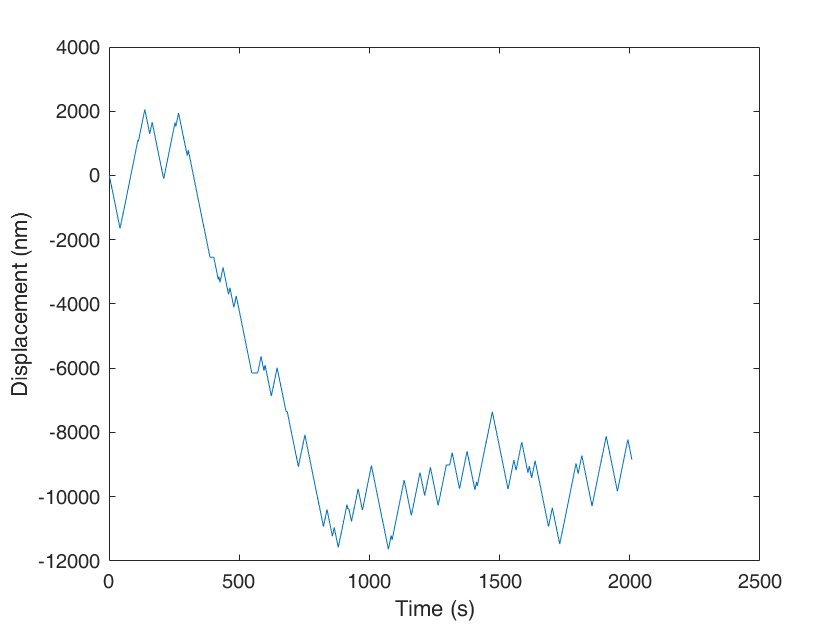

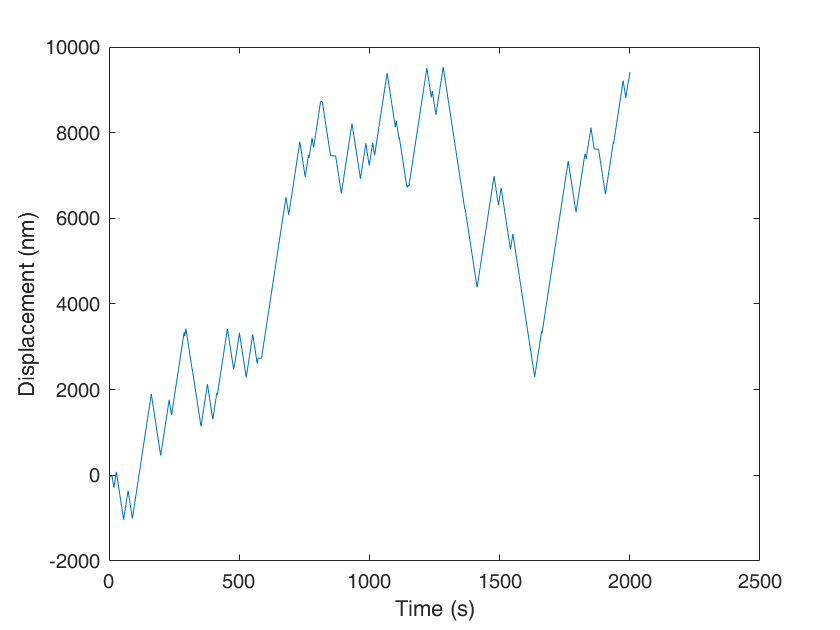

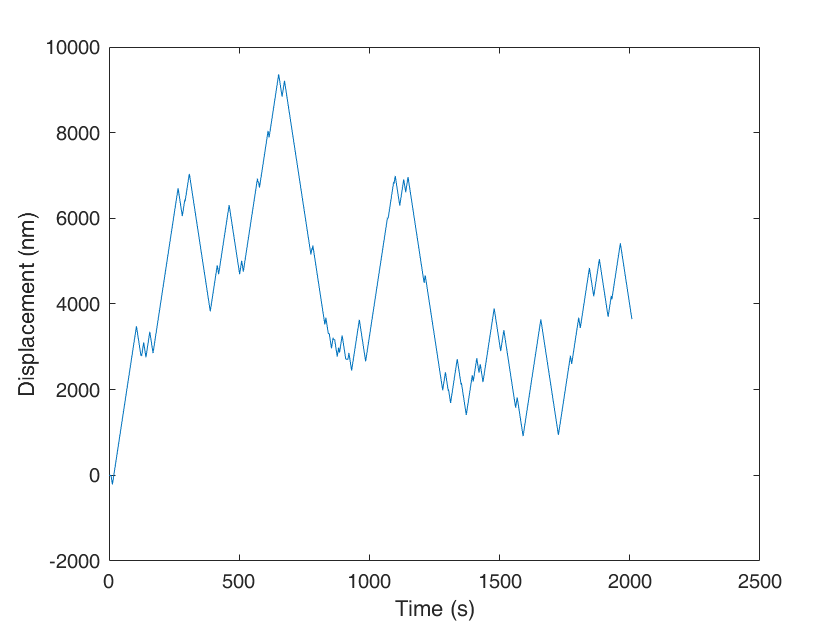

motorState.motorConcentration =1e2;%arb units, essentiall scaling of low synthase concentration data here

for ii =1:3
    [dynamics] = lipowskiWithUnbindingSim(motorState,simPar);
    t=dynamics.t;
    x=dynamics.x;
    figure;
    plot(t,x);
    ylabel('Displacement (nm)');
    xlabel('Time (s)');
    dynamics1High{ii}=dynamics;
end

Best example high conc, 3

pretty combined figure

lineWidth = 1;
figure;
subplot(3,3,[1:3]);
vertPadUm = 1;
t=dynamics1Low{3}.t;
x=dynamics1Low{3}.x/1e3;
plot(t,x,'LineWidth',lineWidth,'Color',nMax1Color);
xlim([0 2000]);
ylim([min(x)-vertPadUm,max(x)+vertPadUm])
ylabel('Displacement ({\mu}m)')
hA=gca;
hA.TickDir='out';
hA.Box='off';
subplot(3,3,[4:6]);
vertPadUm = 2;
t=dynamics1Mid{2}.t;
x=dynamics1Mid{2}.x/1e3;
plot(t,x,'LineWidth',lineWidth,'Color',nMax1Color);
xlim([0 2000]);
ylim([min(x)-vertPadUm,max(x)+vertPadUm])
hA=gca;
hA.TickDir='out';
hA.Box='off';
ylabel('Displacement ({\mu}m)')
subplot(3,3,[7:9]);
vertPadUm = 1;
t=dynamics1High{3}.t;
x=dynamics1High{3}.x/1e3;
plot(t,x,'LineWidth',lineWidth,'Color',nMax1Color);
ylabel('Displacement ({\mu}m)')
xlabel('Time (s)')
hA=gca;
hA.TickDir='out';
hA.Box='off';
xlim([0 2000]);
ylim([min(x)-vertPadUm,max(x)+vertPadUm])
h1 = gcf; 
h1.Color=[1 1 1]

h1 =   Figure (14) with properties:

      Number: 14
        Name: ''
       Color: [1 1 1]
    Position: [1000 918 560 420]
       Units: 'pixels'

  Show all properties


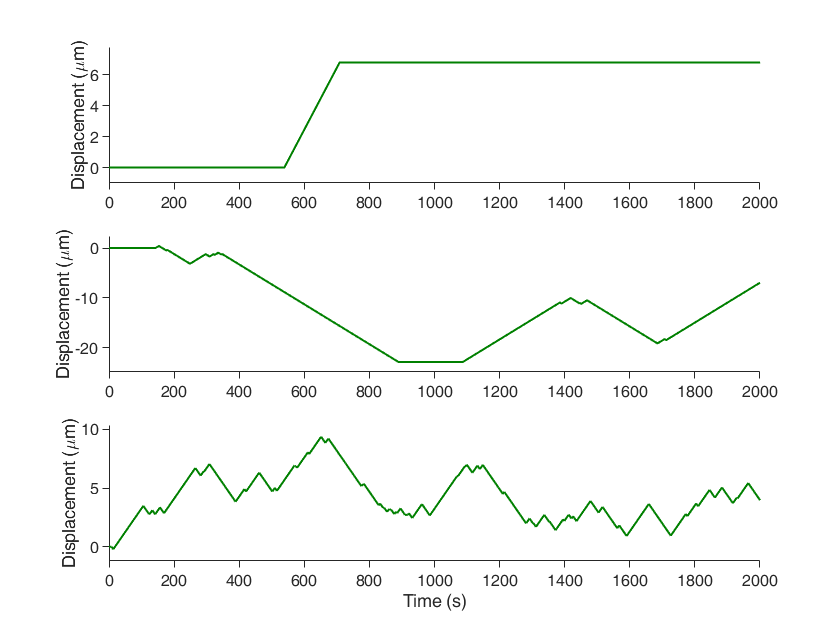

set(h1,'Visible','on');
saveas(h1, 'exemplarTracksNmax1.fig');
saveas(h1, 'exemplarTracksNmax1.pdf');

**Nmax=Inf**

%Nmax = inf each side (max number of motors)
motorState.Nmax = inf;


**Low concentration**

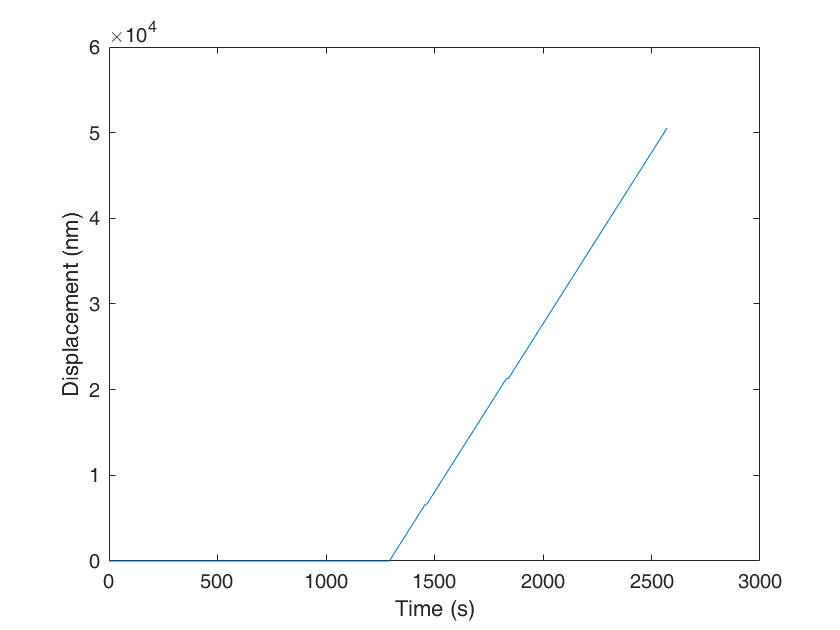

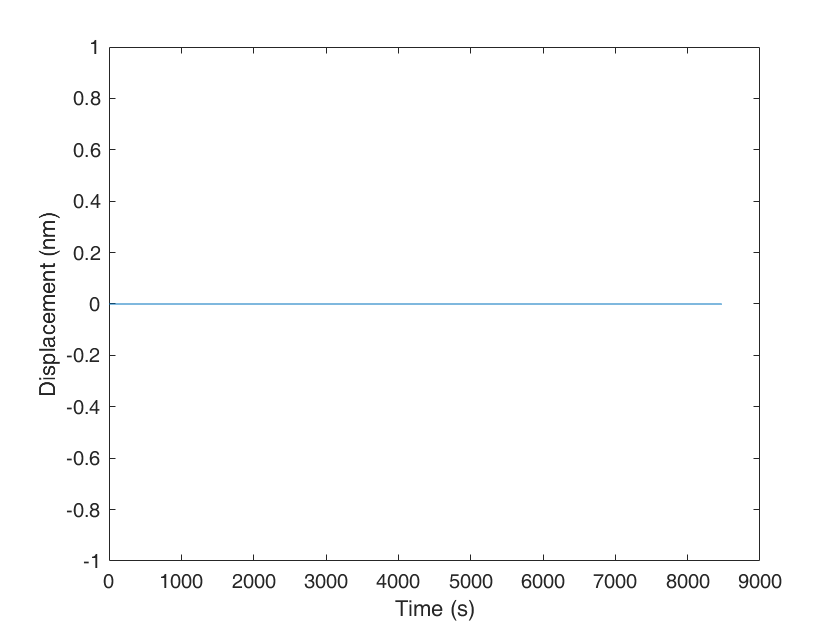

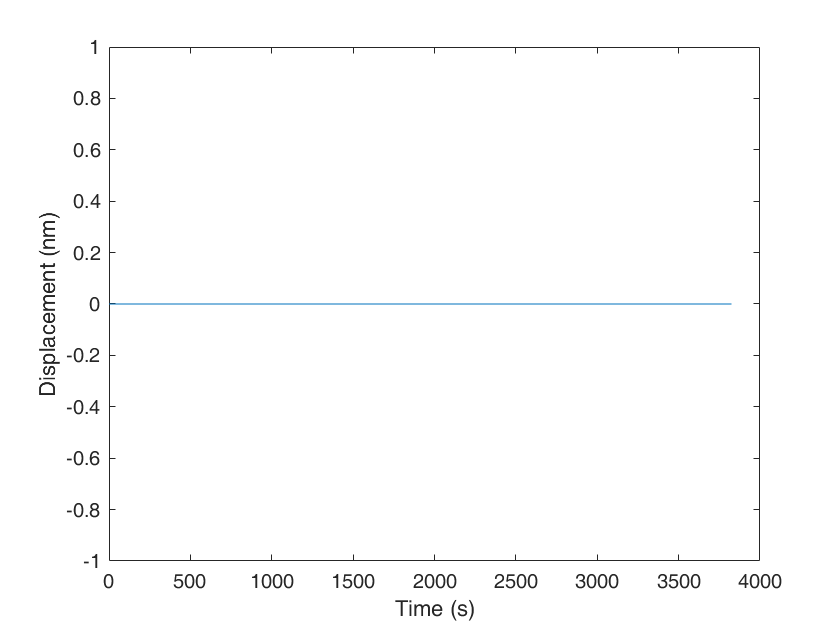

motorState.motorConcentration =1e-2;%arb units, essentiall scaling of low synthase concentration data here

for ii=1:3
    [dynamics] = lipowskiWithUnbindingSim(motorState,simPar);
    t=dynamics.t;
    x=dynamics.x;
    dynamicsInfLow{ii}=dynamics;
    figure;
    plot(t,x);
    ylabel('Displacement (nm)');
    xlabel('Time (s)');
end

Best =1

**Intermediate concentration**

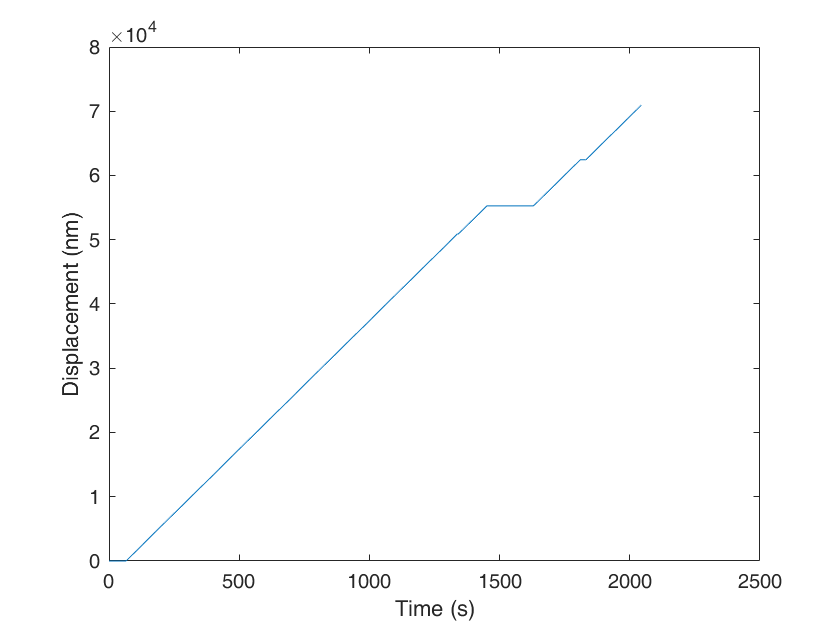

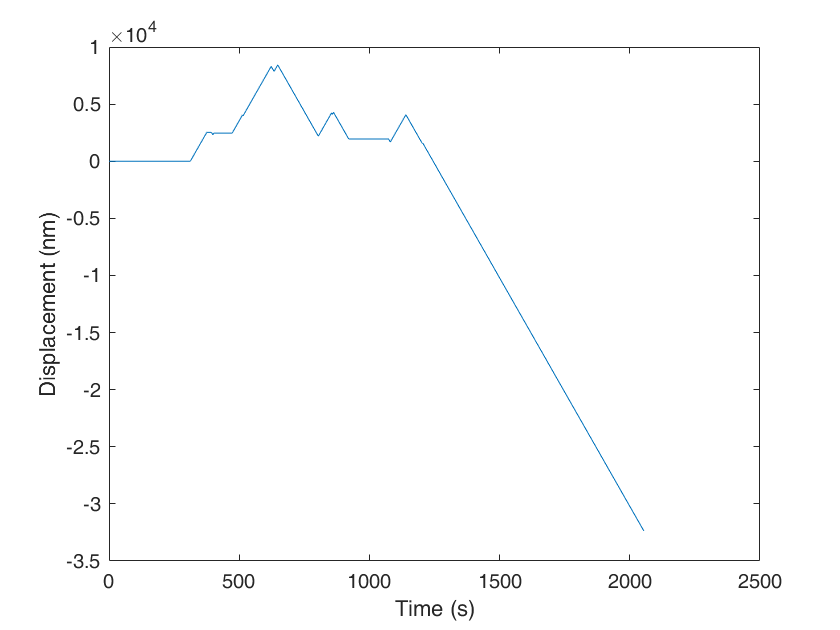

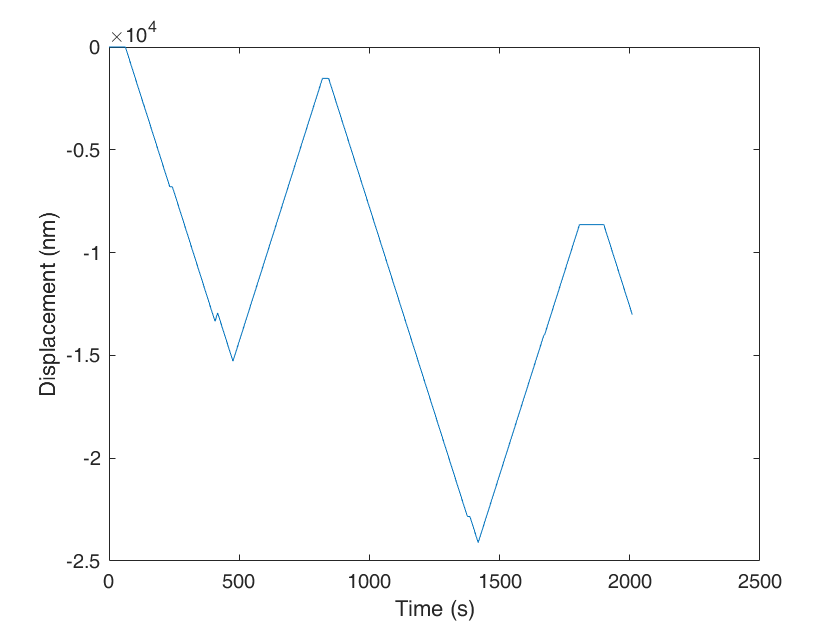

motorState.motorConcentration =1e0;%arb units, essentiall scaling of low synthase concentration data here

for ii = 1:3
    [dynamics] = lipowskiWithUnbindingSim(motorState,simPar);
    t=dynamics.t;
    x=dynamics.x;
    figure;
    plot(t,x);
    ylabel('Displacement (nm)');
    xlabel('Time (s)');
    dynamicsInfMid{ii}=dynamics;
end

Best = 2

**High concentration**

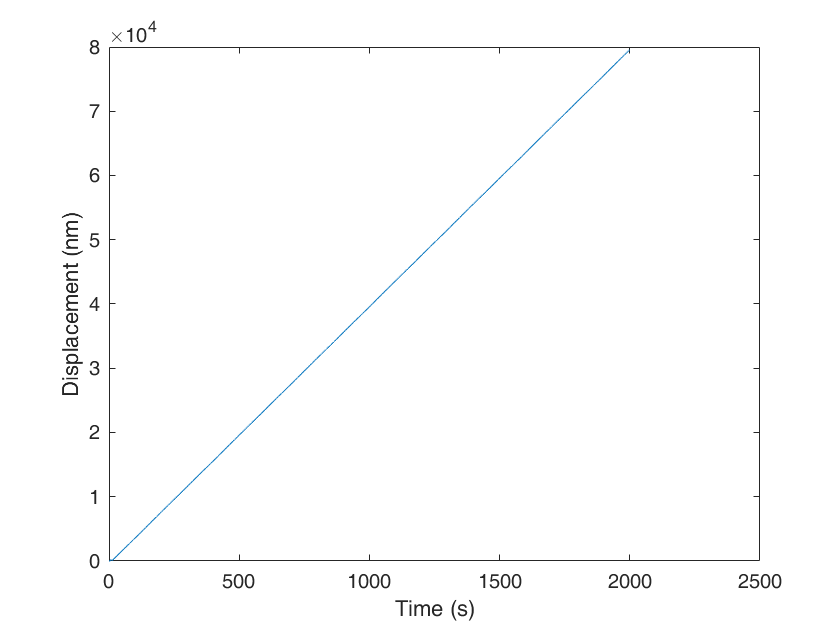

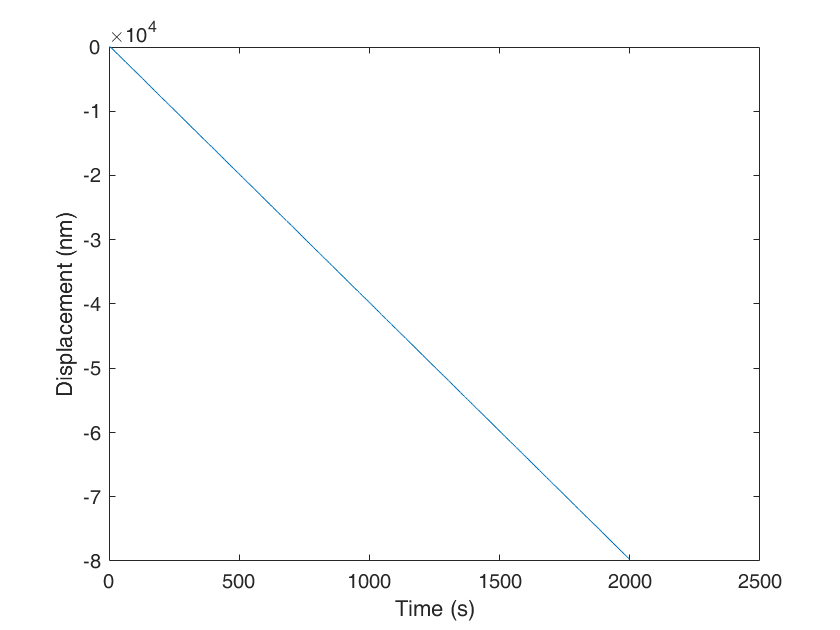

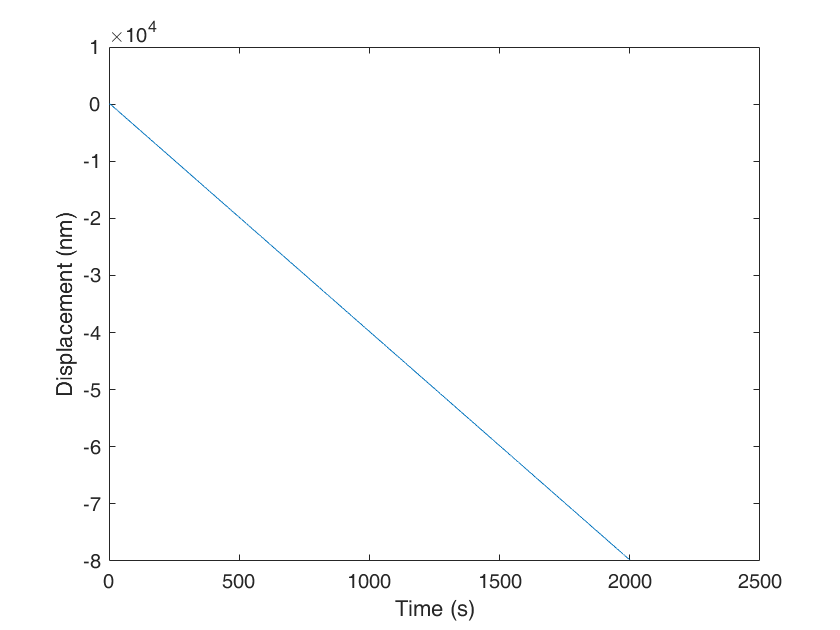

motorState.motorConcentration =1e2;%arb units, essentiall scaling of low synthase concentration data here

for ii =1:3
    [dynamics] = lipowskiWithUnbindingSim(motorState,simPar);
    t=dynamics.t;
    x=dynamics.x;
    figure;
    plot(t,x);
    ylabel('Displacement (nm)');
    xlabel('Time (s)');
    dynamicsInfHigh{ii}=dynamics;
end

BEST = 2

lineWidth = 1;
figure;
subplot(3,3,[1:3]);
vertPadUm = 1;
t=dynamicsInfLow{1}.t;
x=dynamicsInfLow{1}.x/1e3;
plot(t,x,'LineWidth',lineWidth,'Color',nMaxInfColor);
xlim([0 2000]);
ylim([min(x)-vertPadUm,max(x)+vertPadUm])
ylabel('Displacement ({\mu}m)')
hA=gca;
hA.TickDir='out';
hA.Box='off';
subplot(3,3,[4:6]);
vertPadUm = 2;
t=dynamicsInfMid{3}.t;
x=dynamicsInfMid{3}.x/1e3;
plot(t,x,'LineWidth',lineWidth,'Color',nMaxInfColor);
xlim([0 2000]);
ylim([min(x)-vertPadUm,max(x)+vertPadUm])
hA=gca;
hA.TickDir='out';
hA.Box='off';
ylabel('Displacement ({\mu}m)')
subplot(3,3,[7:9]);
vertPadUm = 1;
t=dynamicsInfHigh{2}.t;
x=dynamicsInfHigh{2}.x/1e3;
plot(t,x,'LineWidth',lineWidth,'Color',nMaxInfColor);
ylabel('Displacement ({\mu}m)')
xlabel('Time (s)')
hA=gca;
hA.TickDir='out';
hA.Box='off';
xlim([0 2000]);
ylim([min(x)-vertPadUm,max(x)+vertPadUm])
h1 = gcf; 
h1.Color=[1 1 1]

h1 =   Figure (28) with properties:

      Number: 28
        Name: ''
       Color: [1 1 1]
    Position: [1000 918 560 420]
       Units: 'pixels'

  Show all properties


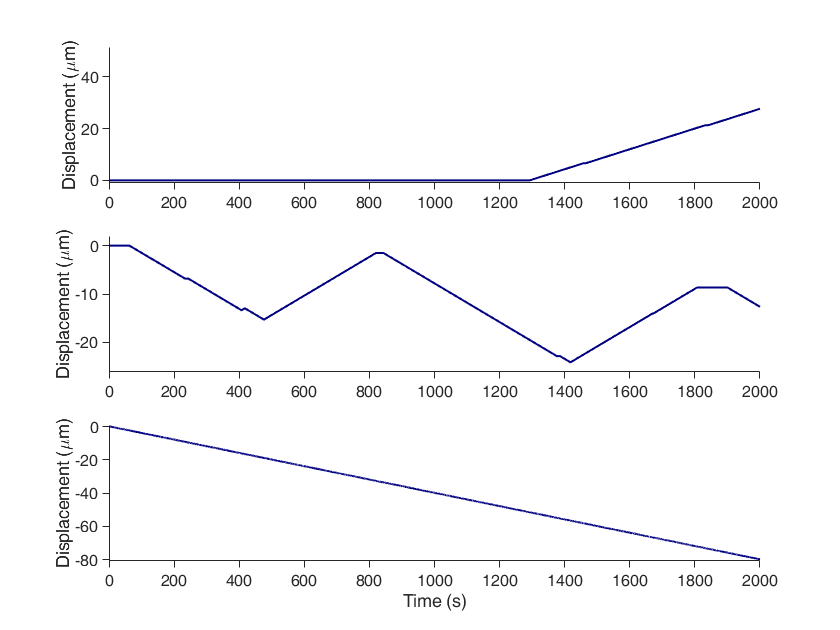

set(h1,'Visible','on');
saveas(h1, 'exemplarTracksNmaxInf.fig');
saveas(h1, 'exemplarTracksNmaxInf.pdf');

**Relevant averaged properties for plotting**

**Reversal frequency - main text**

load('lipowskiSimInitialResults220310.mat')

figure;
hold all;
errorbar(motorConcRange*1e2, reversal_processive1(:,1),...
    reversal_processive1(:,1)-reversal_processive1(:,2),reversal_processive1(:,3)-reversal_processive1(:,1),'-o',...
    'Color',nMax1Color,'MarkerEdgeColor',nMax1Color,'MarkerFaceColor',nMax1Color,...
    'LineWidth',1);
errorbar(motorConcRange*1e2, reversal_processiveInf(:,1),...
    reversal_processiveInf(:,1)-reversal_processiveInf(:,2),reversal_processiveInf(:,3)-reversal_processiveInf(:,1),'-o',...
    'Color',nMaxInfColor,'MarkerEdgeColor',nMaxInfColor,'MarkerFaceColor',nMaxInfColor,...
    'LineWidth',1);

hA=gca;
hA.XScale='log';
hA.TickDir='out';
hA.Box='off';
% hA.YScale='log';
% xlim([10^-0.1 10^4])
legend('End-binding','Unlimited binding','Location','northwest')
legend('boxoff');
xlabel('Synthase concentration (arb. units)');
ylabel('Reversal rate (s^{-1})')
h1 = gcf; 
h1.Color=[1 1 1]

h1 =   Figure (30) with properties:

      Number: 30
        Name: ''
       Color: [1 1 1]
    Position: [1000 918 560 420]
       Units: 'pixels'

  Show all properties


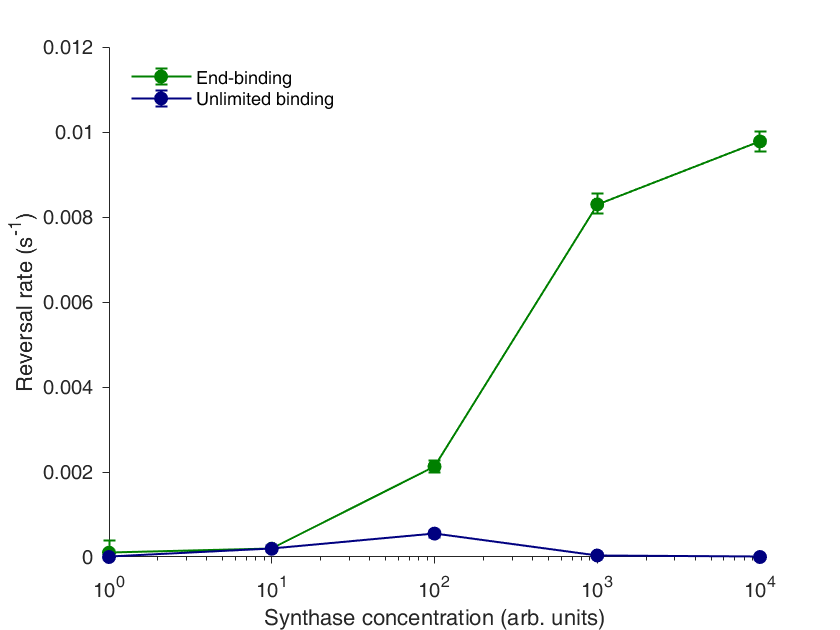

set(h1,'Visible','on');
saveas(h1, 'ReversalRates.fig');
saveas(h1, 'ReversalRates.pdf');

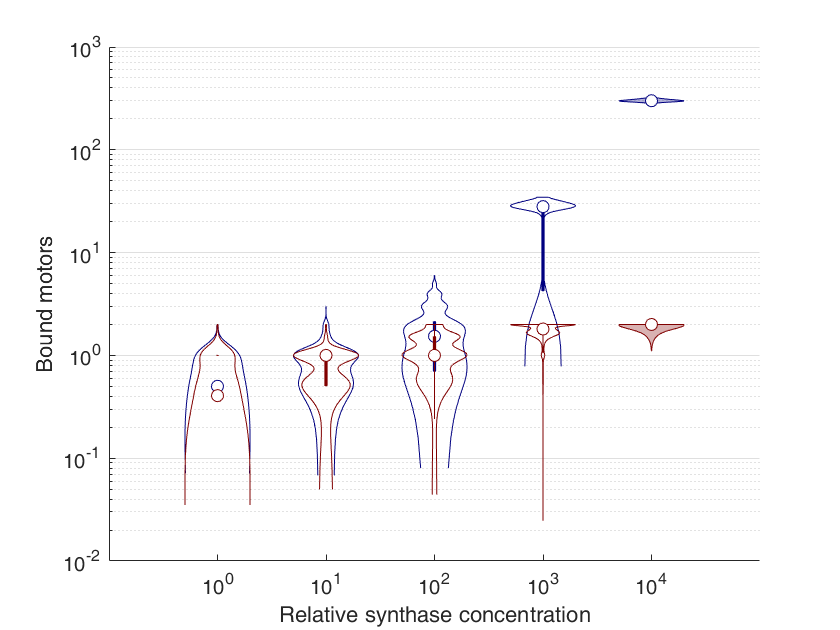


figure;
hold all;
violinplot(cell2struct(NmotorNmaxInf,fieldName,2),[],'ShowData',false,'ViolinColor',[0 0 0.5], 'EdgeColor',[0 0 0.5],'BoxColor',[0 0 0.5]);
violinplot(cell2struct(NmotorNmax1,fieldName,2),[],'ShowData',false,'ViolinColor',[0.5 0 0], 'EdgeColor',[0.5 0 0],'BoxColor',[0.5 0 0]);
hA=gca;
hA.YScale='log';
hA.YGrid='on';
xlabel('Relative synthase concentration');
ylabel('Bound motors')
hA.XTickLabel=categoryName;

for ii = 1:numel(motorConcRange)
    NmotorNmax1Array(ii,:) = prctile(NmotorNmax1{ii},[50 25 75]); %processivity percentiles, in um
    NmotorNmaxInfArray(ii,:) =  prctile(NmotorNmaxInf{ii},[50 25 75]);
end
figure;
hold all
errorbar(motorConcRange*1e2, NmotorNmax1Array(:,1),...
    NmotorNmax1Array(:,1)-NmotorNmax1Array(:,2),NmotorNmax1Array(:,3)-NmotorNmax1Array(:,1),'-o',...
    'Color',nMax1Color,'MarkerEdgeColor',nMax1Color,'MarkerFaceColor',nMax1Color,...
    'LineWidth',1);
errorbar(motorConcRange*1e2, NmotorNmaxInfArray(:,1),...
    NmotorNmaxInfArray(:,1)-NmotorNmaxInfArray(:,2),NmotorNmaxInfArray(:,3)-NmotorNmaxInfArray(:,1),'-o',...
    'Color',nMaxInfColor,'MarkerEdgeColor',nMaxInfColor,'MarkerFaceColor',nMaxInfColor,...
    'LineWidth',1);
plot([10^0, 10^4],[2 2],'k--')

hA=gca;
hA.XScale='log';
hA.TickDir='out';
hA.Box='off';
hA.YScale='log';
legend('End-binding','Unlimited binding','Location','northwest')
legend('boxoff');
xlabel('Synthase concentration (arb. units)');
ylabel('Number of bound motors');
h1 = gcf; 
h1.Color=[1 1 1];
set(h1,'Visible','on');
saveas(h1, 'noOfMotors.fig');

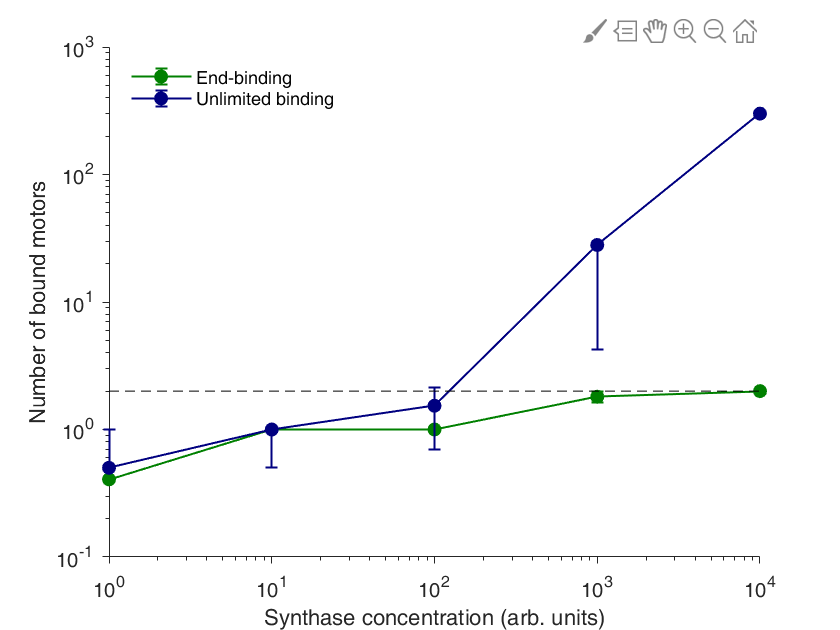

saveas(h1, 'noOfMotors.pdf');

this needs a bit of work then. Maybe SI?

Processivity, both models. Main text

Motile fraction, both models -main text

Speed distribution - SI?

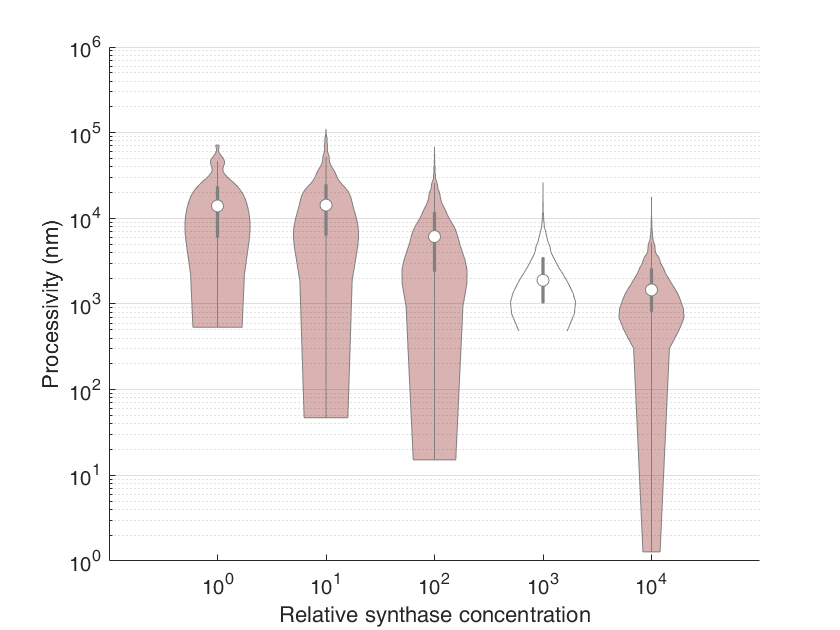

figure;
violinplot(cell2struct(processivityNmax1,fieldName,2),[],'ShowData',false,'ViolinColor',[0.5 0 0]);
xlabel('Relative synthase concentration');
ylabel('Processivity (nm)');
hA=gca;
hA.XTickLabel=categoryName;
hA.YScale='log';
hA.YGrid='on';

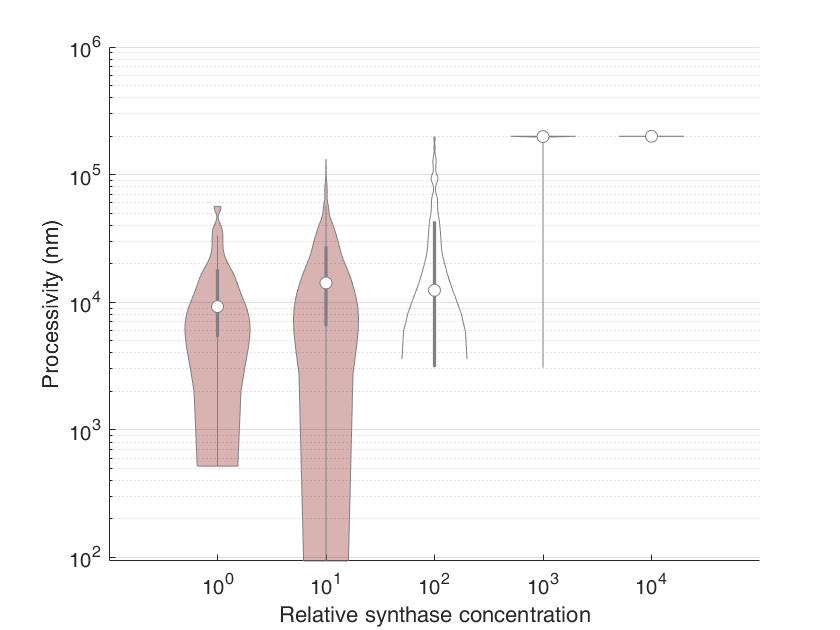

figure;
violinplot(cell2struct(processivityNmaxInf,fieldName,2),[],'ShowData',false,'ViolinColor',[0.5 0 0]);
xlabel('Relative synthase concentration');
ylabel('Processivity (nm)');
hA=gca;
hA.XTickLabel=categoryName;
hA.YScale='log';
hA.YGrid='on';

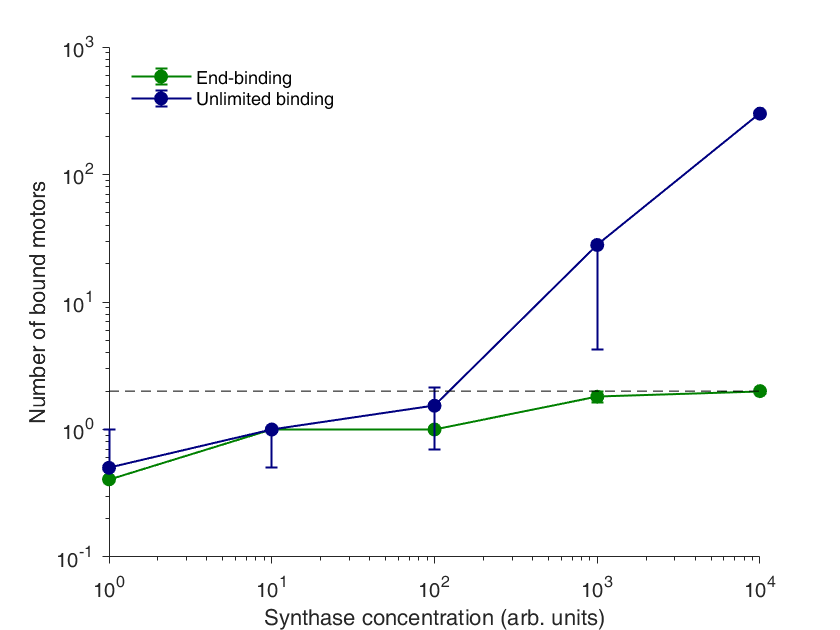

for ii = 1:numel(motorConcRange)
    procNmax1(ii,:) = prctile(processivityNmax1{ii},[50 25 75])/1e3; %processivity percentiles, in um
    procNmaxInf(ii,:) =  prctile(processivityNmaxInf{ii},[50 25 75])/1e3;
end
figure;
hold all;
errorbar(motorConcRange*1e2,procNmax1(:,1),procNmax1(:,1)-procNmax1(:,2),procNmax1(:,3)-procNmax1(:,1),'-o',...
        'Color',nMax1Color,'MarkerEdgeColor',nMax1Color,'MarkerFaceColor',nMax1Color,...
    'LineWidth',1);
errorbar(motorConcRange*1e2,procNmaxInf(:,1),procNmaxInf(:,1)-procNmaxInf(:,2),procNmaxInf(:,3)-procNmaxInf(:,1),'-o',...
        'Color',nMaxInfColor,'MarkerEdgeColor',nMaxInfColor,'MarkerFaceColor',nMaxInfColor,...
    'LineWidth',1);

ylabel('Processivity ({\mu}m)');
hA=gca;
hA.YScale='log';
hA.XScale='log';
hA.YGrid='on';
ylim([10^-0.2 10^2.5])
legend('End-binding','Unlimited binding','Location','northwest')
legend('boxoff');

hA.TickDir='out';
hA.Box='off';

xlabel('Synthase concentration (arb. units)');

h1 = gcf; 
h1.Color=[1 1 1];
set(h1,'Visible','on');
saveas(h1, 'Processivity.fig');

saveas(h1, 'Processivity.pdf');

Motile fraction, both models -main text

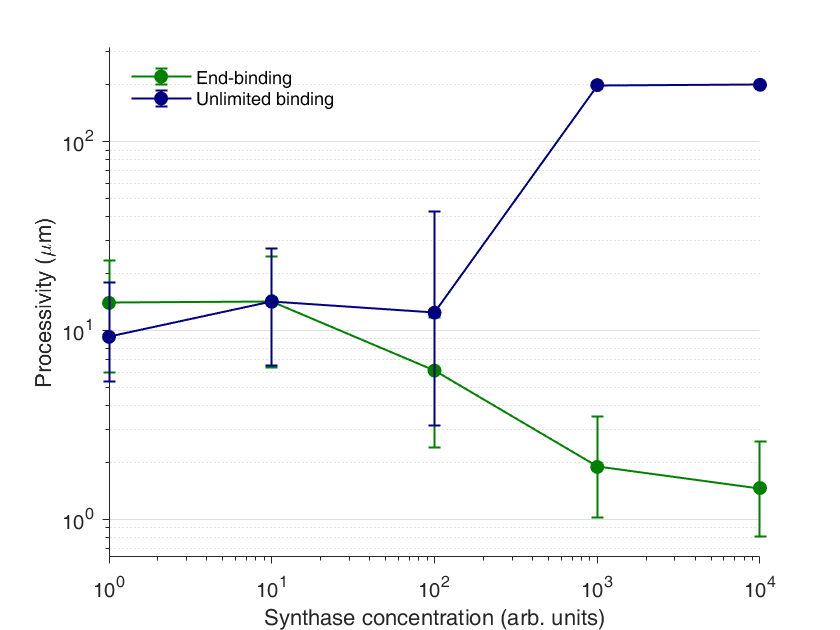

%faction motile v static
percentMotileNmax1=fractionMotileNmax1*100;
percentMotileNmaxInf=fractionMotileNmaxInf*100;
figure;
hold all;
errorbar(motorConcRange*1e2, percentMotileNmax1(:,1),...
    percentMotileNmax1(:,1)-percentMotileNmax1(:,2),percentMotileNmax1(:,3)-percentMotileNmax1(:,1),'-o',...
            'Color',nMax1Color,'MarkerEdgeColor',nMax1Color,'MarkerFaceColor',nMax1Color,...
    'LineWidth',1);
errorbar(motorConcRange*1e2, percentMotileNmaxInf(:,1),...
    percentMotileNmaxInf(:,1)-percentMotileNmaxInf(:,2),percentMotileNmaxInf(:,3)-percentMotileNmaxInf(:,1),'-o',...
            'Color',nMaxInfColor,'MarkerEdgeColor',nMaxInfColor,'MarkerFaceColor',nMaxInfColor,...
    'LineWidth',1);

legend('End-binding','Unlimited binding','Location','southeast')
legend('boxoff');
hA=gca;
hA.XScale='log';

ylabel('Motile complexes (%)');

hA.TickDir='out';
hA.Box='off';

xlabel('Synthase concentration (arb. units)');

h1 = gcf; 
h1.Color=[1 1 1];
set(h1,'Visible','on');
saveas(h1, 'Motile complexes.fig');
saveas(h1, 'Motile complexes.pdf');

Speed distribution - SI?

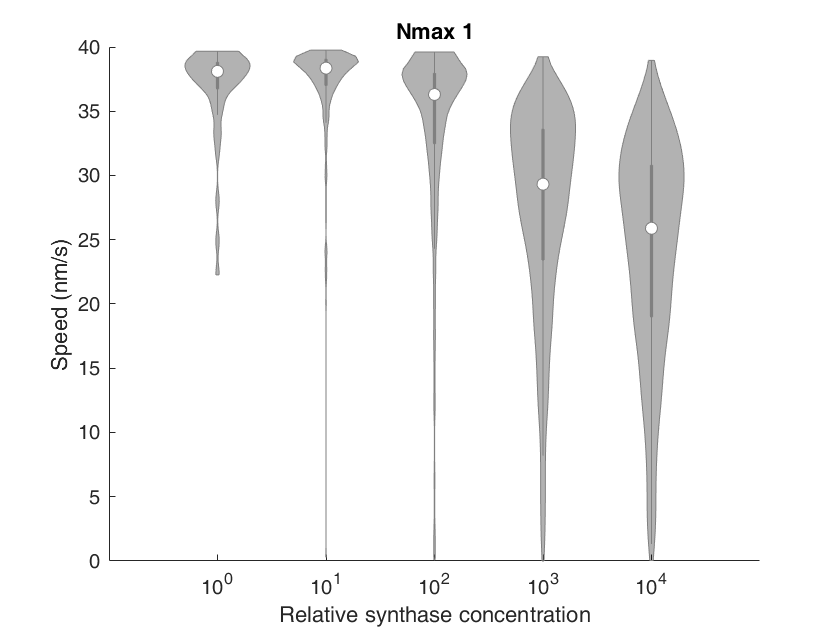

%plot only the motile population
for ii = 1:numel(motorConcRange)
    speedNmax1{ii}= simResultNmax1{ii}.speed(simResultNmax1{ii}.isMotile==1);
    speedNmaxInf{ii}= simResultNmaxInf{ii}.speed(simResultNmaxInf{ii}.isMotile==1);
    speedNmax1Array(ii,:) =  prctile(speedNmax1{ii},[50,25,75]);
    speedNmaxInfArray(ii,:) =  prctile(speedNmaxInf{ii},[50,25,75]);
end
figure;
violinplot(cell2struct(speedNmax1,fieldName,2),[], 'ShowData',false,'ViolinColor',[0 0 0]);
xlabel('Relative synthase concentration');
ylabel('Speed (nm/s)');
hA=gca;
hA.XTickLabel=categoryName;
title('Nmax 1')

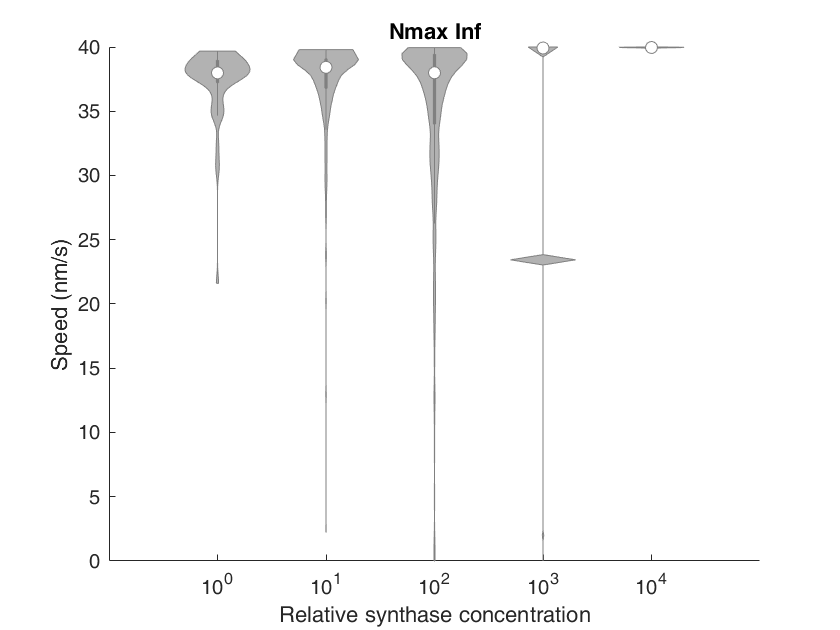

figure;
violinplot(cell2struct(speedNmaxInf,fieldName,2),[], 'ShowData',false,'ViolinColor',[0 0 0]);
xlabel('Relative synthase concentration');
ylabel('Speed (nm/s)');
hA=gca;
hA.XTickLabel=categoryName;
title('Nmax Inf')

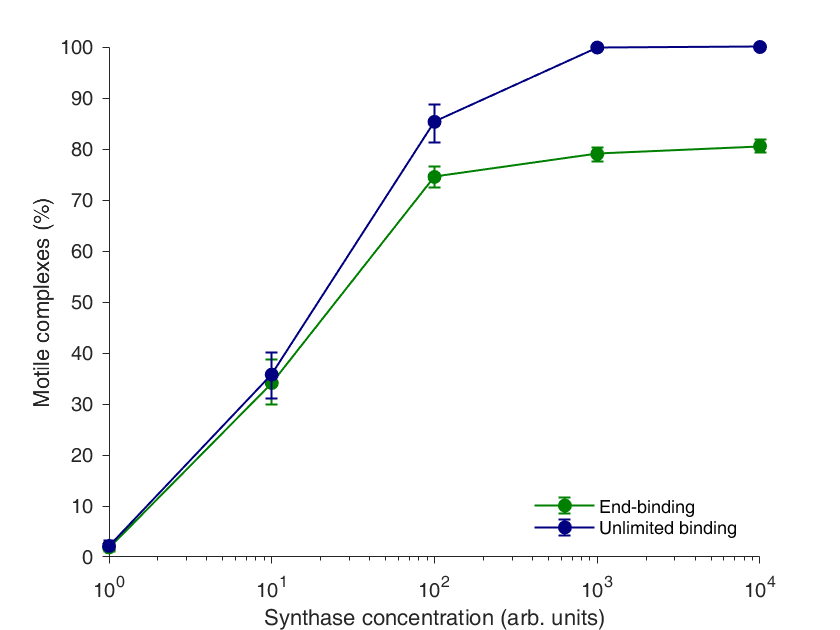

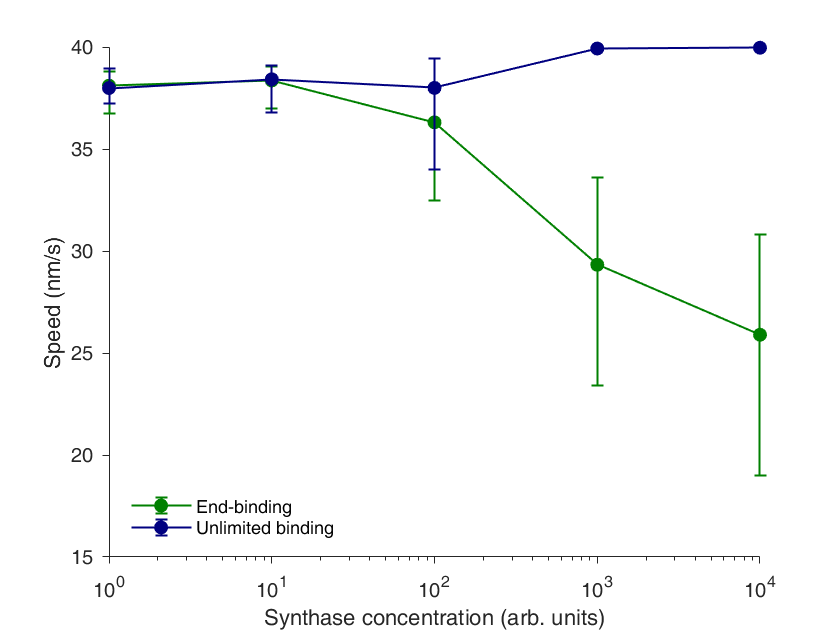

figure;
hold all
errorbar(motorConcRange*1e2, speedNmax1Array(:,1),...
    speedNmax1Array(:,1)-speedNmax1Array(:,2),speedNmax1Array(:,3)-speedNmax1Array(:,1),'-o',...
                'Color',nMax1Color,'MarkerEdgeColor',nMax1Color,'MarkerFaceColor',nMax1Color,...
    'LineWidth',1);
errorbar(motorConcRange*1e2, speedNmaxInfArray(:,1),...
    speedNmaxInfArray(:,1)-speedNmaxInfArray(:,2),speedNmaxInfArray(:,3)-speedNmaxInfArray(:,1),'-o',...
                'Color',nMaxInfColor,'MarkerEdgeColor',nMaxInfColor,'MarkerFaceColor',nMaxInfColor,...
    'LineWidth',1);
legend('End-binding','Unlimited binding','Location','southwest')
legend('boxoff');
hA=gca;
hA.XScale='log';

ylabel('Speed (nm/s)');


hA.TickDir='out';
hA.Box='off';

xlabel('Synthase concentration (arb. units)');

h1 = gcf; 
h1.Color=[1 1 1];
set(h1,'Visible','on');
saveas(h1, 'Speed.fig');
saveas(h1, 'Speed.pdf');

Processive and static lifetimes

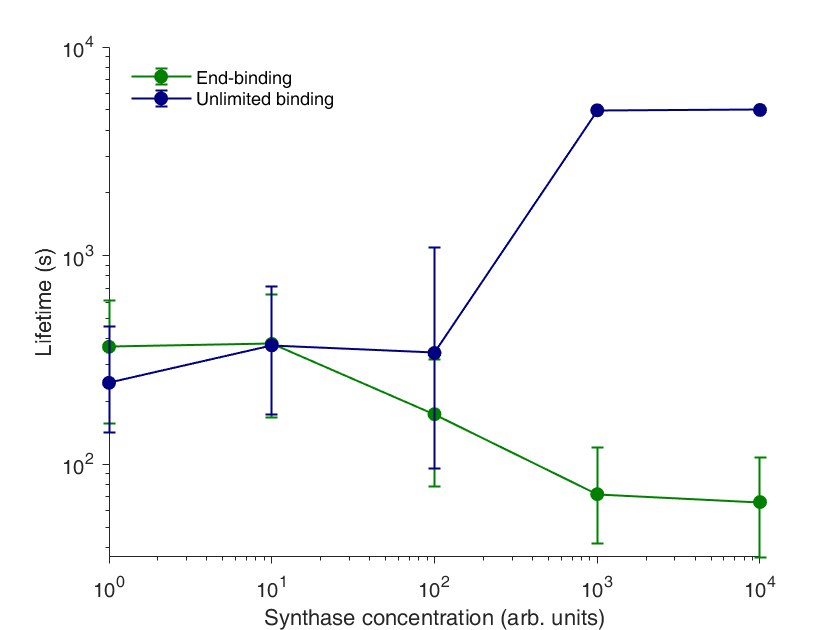

for ii = 1:numel(motorConcRange)
    lifetimeProcessiveNmax1Array(ii,:) =  prctile(lifetimeProcessiveNmax1{ii},[50,25,75]);
    lifetimeStaticNmax1Array(ii,:) =  prctile(lifetimeStaticNmax1{ii},[50,25,75]);
    lifetimeProcessiveNmaxInfArray(ii,:) =  prctile(lifetimeProcessiveNmaxInf{ii},[50,25,75]);
    lifetimeStaticNmaxInfArray(ii,:) =  prctile(lifetimeStaticNmaxInf{ii},[50,25,75]);    
end
figure;
hold all
errorbar(motorConcRange*1e2, lifetimeProcessiveNmax1Array(:,1),...
    lifetimeProcessiveNmax1Array(:,1)-lifetimeProcessiveNmax1Array(:,2),lifetimeProcessiveNmax1Array(:,3)-lifetimeProcessiveNmax1Array(:,1),'-o',...
                    'Color',nMax1Color,'MarkerEdgeColor',nMax1Color,'MarkerFaceColor',nMax1Color,...
    'LineWidth',1);

errorbar(motorConcRange*1e2, lifetimeProcessiveNmaxInfArray(:,1),...
    lifetimeProcessiveNmaxInfArray(:,1)-lifetimeProcessiveNmaxInfArray(:,2),lifetimeProcessiveNmaxInfArray(:,3)-lifetimeProcessiveNmaxInfArray(:,1),'-o',...
                    'Color',nMaxInfColor,'MarkerEdgeColor',nMaxInfColor,'MarkerFaceColor',nMaxInfColor,...
    'LineWidth',1);
legend('End-binding','Unlimited binding','Location','northwest');
legend('boxoff');
hA=gca;
hA.XScale='log';
hA.YScale='log';

ylabel('Lifetime (s)');
%title('Lifetime, motile filaments (s)')
hA.TickDir='out';
hA.Box='off';
xlabel('Synthase concentration (arb. units)');
hA.TickDir='out';
hA.Box='off';
h1 = gcf; 
h1.Color=[1 1 1];
set(h1,'Visible','on');
saveas(h1, 'Lifetime motile state.fig');
saveas(h1, 'Lifetime motile state.pdf');

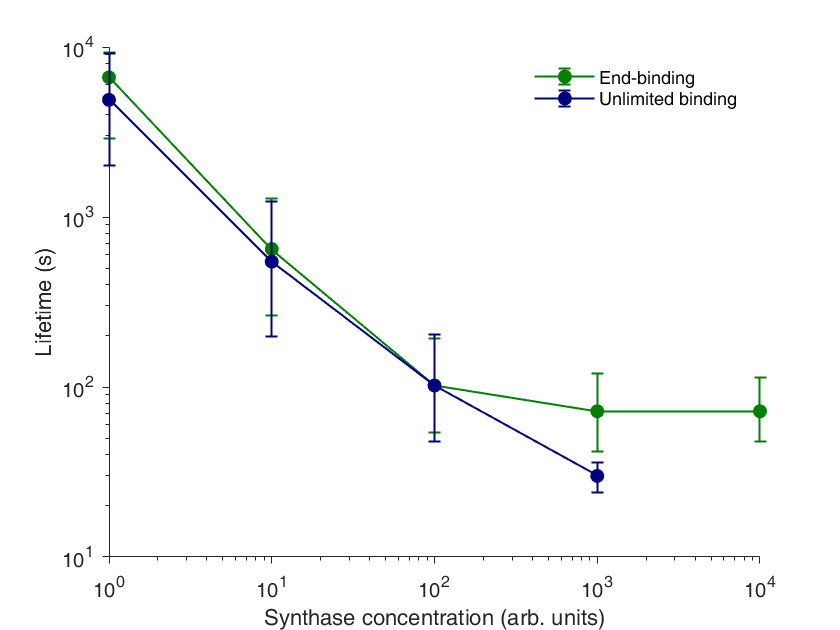


figure;
hold all
errorbar(motorConcRange*1e2, lifetimeStaticNmax1Array(:,1),...
    lifetimeStaticNmax1Array(:,1)-lifetimeStaticNmax1Array(:,2),lifetimeStaticNmax1Array(:,3)-lifetimeStaticNmax1Array(:,1),'-o',...
    'Color',nMax1Color,'MarkerEdgeColor',nMax1Color,'MarkerFaceColor',nMax1Color,...
    'LineWidth',1);

errorbar(motorConcRange*1e2, lifetimeStaticNmaxInfArray(:,1),...
    lifetimeStaticNmaxInfArray(:,1)-lifetimeStaticNmaxInfArray(:,2),lifetimeStaticNmaxInfArray(:,3)-lifetimeStaticNmaxInfArray(:,1),'-o',...
    'Color',nMaxInfColor,'MarkerEdgeColor',nMaxInfColor,'MarkerFaceColor',nMaxInfColor,...
    'LineWidth',1);
legend('End-binding','Unlimited binding','Location','northeast');
legend('boxoff');
hA=gca;
hA.XScale='log';
hA.YScale='log';

ylabel('Lifetime (s)');
%title('Lifetime, static filaments (s)')
hA.TickDir='out';
hA.Box='off';
xlabel('Synthase concentration (arb. units)');
hA.TickDir='out';
hA.Box='off';
h1 = gcf; 
h1.Color=[1 1 1];
set(h1,'Visible','on');
saveas(h1, 'Lifetime static state.fig');
saveas(h1, 'Lifetime static state.pdf');